## Initialize a wave vortex transform

To [initialize a WVTransformConstantStratification](http://wavevortexmodel.org/classes/transforms/wvtransformconstantstratification/wvtransformconstantstratification.html) you need to know the domain size (100 km, 100 km, 1300 m) and the number of grid points. This constructor returns an instance of the class, wvt. Further below we will initialize with variable stratification. 

wvt = WVTransformConstantStratification([100e3, 100e3, 1300],[64, 64, 65], N0=5.2e-3,latitude=30);

The operation nonlinearFlux with variables {Fp,Fm,F0,} has been removed and the operation WVNonlinearFlux with variables {Fp,Fm,F0,} has been added.


## Add an internal wave

omega=wvt.initWithWaveModes(kMode=5,lMode=0,j=3,phi=0,u=0.2,sign=1);

## Make a few plots

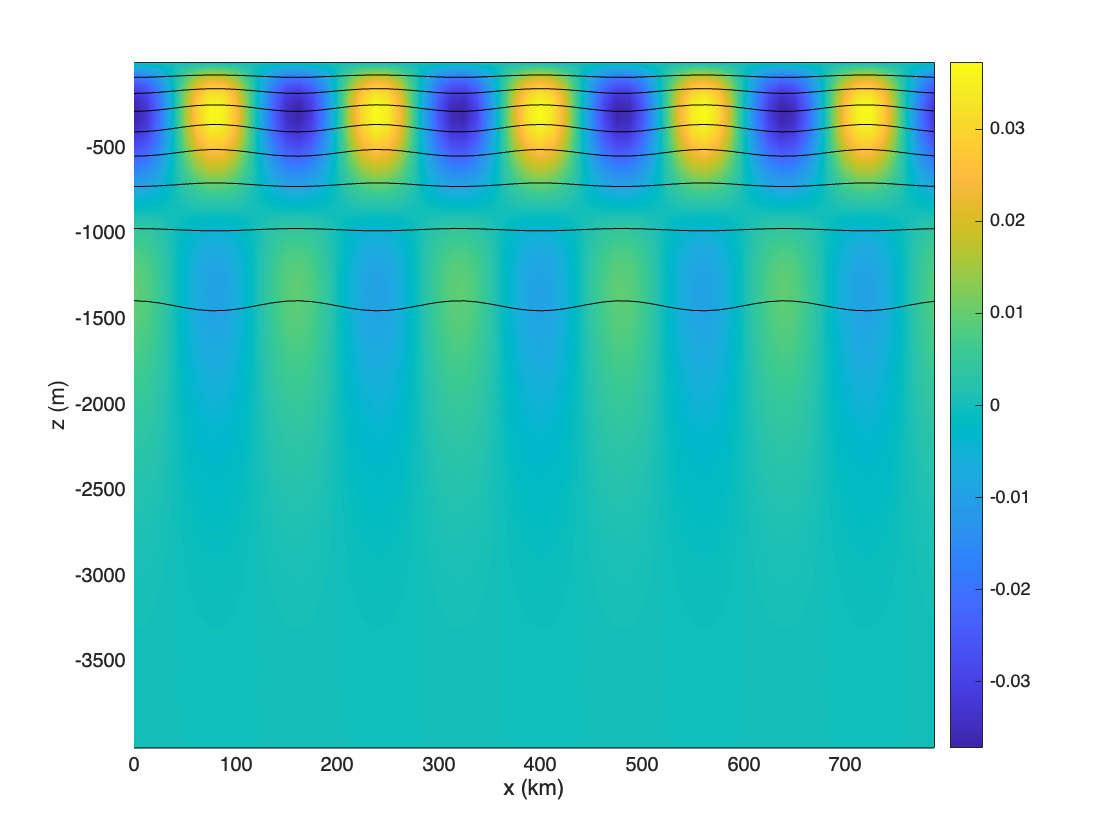

wvt.t = (2*pi/omega)*0.5;
figure
pcolor(wvt.x/1000,wvt.z,squeeze(wvt.rho_e(:,1,:)).'); colorbar; clim([min(wvt.rho_e(:)),max(wvt.rho_e(:))]), shading interp, hold on
contour(wvt.x/1000,wvt.z,squeeze(wvt.rho_total(:,1,:)).',linspace(min(wvt.rho_total(:)),max(wvt.rho_total(:)),10),'k','LineWidth',0.5);
xlabel('x (km)'), ylabel('z (m)')

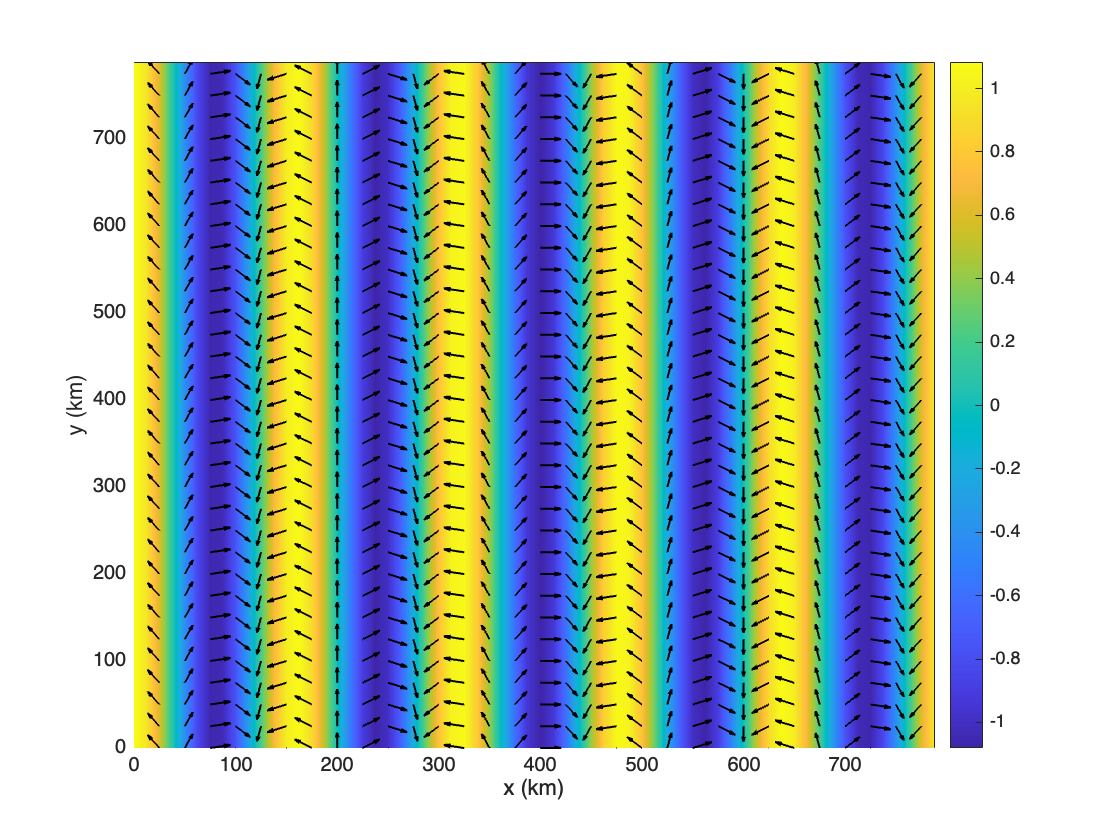

fig = figure();
h = pcolor(wvt.x/1000,wvt.y/1000,100*wvt.ssh.'); colorbar; shading interp, hold on
quiver(wvt.x(1:2:end)/1000,wvt.y(1:2:end)/1000,squeeze(wvt.u(1:2:end,1:2:end,1)).',squeeze(wvt.v(1:2:end,1:2:end,1)).',0.6, 'Color',0*[1 1 1], 'LineWidth',1)
xlabel('x (km)'), ylabel('y (km)')
xlim([min(wvt.x/1000) max(wvt.x/1000)]), ylim([min(wvt.y/1000) max(wvt.y/1000)])

## Initialize a new wave vortex transform

N0 = 3*2*pi/3600;
L_gm = 1300;
N2 = @(z) N0*N0*exp(2*z/L_gm);
wvt = WVTransformHydrostatic([800e3, 800e3, 4000],[64, 64, 65], N2=N2,latitude=30);

The operation nonlinearFlux with variables {Fp,Fm,F0,} has been removed and the operation WVNonlinearFlux with variables {Fp,Fm,F0,} has been added.


## Add an internal wave

[omega,k,l]=wvt.initWithWaveModes(kMode=5,lMode=0,j=2,phi=0,u=0.2,sign=1);
%wvt.initWithGMSpectrum(1.0);

## Make a few plots

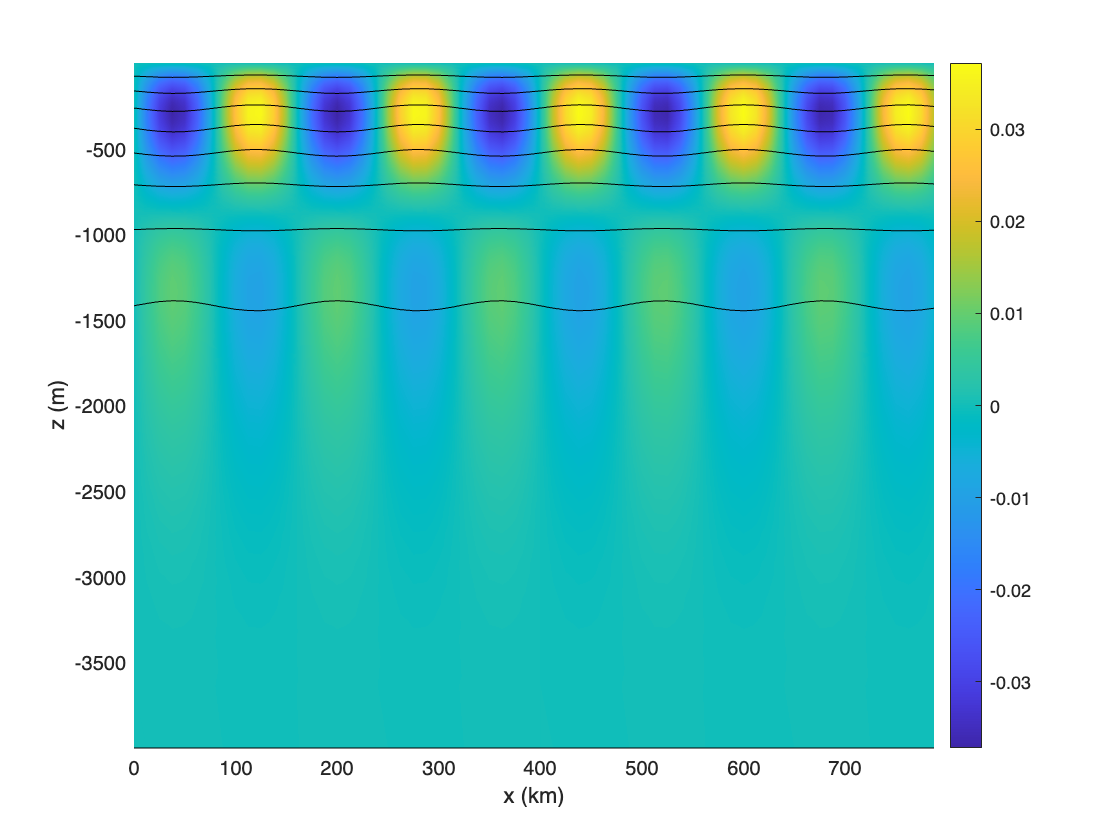

wvt.t = (2*pi/omega)*0.25;
figure
pcolor(wvt.x/1000,wvt.z,squeeze(wvt.rho_e(:,1,:)).'); colorbar; clim([min(wvt.rho_e(:)),max(wvt.rho_e(:))]), shading interp, hold on
contour(wvt.x/1000,wvt.z,squeeze(wvt.rho_total(:,1,:)).',linspace(min(wvt.rho_total(:)),max(wvt.rho_total(:)),10),'k','LineWidth',0.5);
xlabel('x (km)'), ylabel('z (m)')